# Slosh 3D, tilt about x axis 

Different parametrization of the pendulum

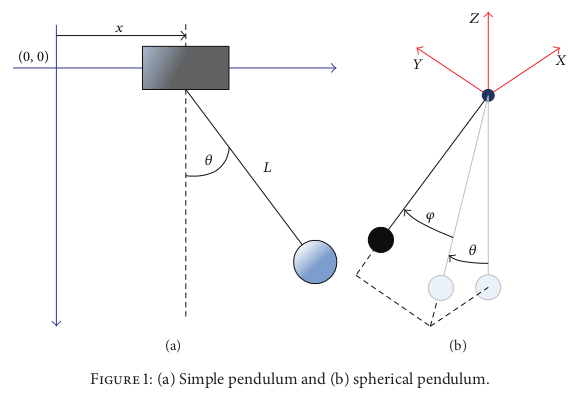

In this code the equation of motion for the pendulum angle representing the sloshing are derived through the use of the Euler-Lagrange equations.

This sloshing model represent only the 3D motion of the tray and a 1D rotation about the x axis of the container.

clc 
clear all

syms theta(t) psi(t) phi(t) beta(t)
syms t 
syms d h l m g M b cs
syms x(t) y(t) z(t)
sympref('AbbreviateOutput',false);

$\theta$ = angle between plane ZY and the mass, angle of the pendulum mapped in xz plane

$\phi$ = angle in the perpendicular direction, between the original pendulum and the mapped pendulum

$\psi$ =  rotation of the pendulum about its longitudinal axis z

$\beta$ = pitch rotation about the x axis of the container

h = height of the container

d = distance from CoM to top of the liquid at rest (for full uniform liquid container it is h/2)

l = length of pendulum

m = mass of pendulum

M = mass of liquid + container

b = damping coefficient

J = moment of inertia of the pendulum mass

## Derivation of the pendulum coordinates

Through the use of homogeneous transformation matrices infer the position of the pendulum mass and of the liquid+container mass in the world reference frame.

Assume the following reference frames:

- Inertial frame

- Frame of the container CoM with origin assumed to be at a distance d from the pivot

- Frame of the pivot of the pendulum

- Frame of the pendulum mass

### World to CoM

Derive the homogeneous transformation matrix from the world to the CoM reference frame.

Define rotation matrix (rotation of around the x-axis)

% Rotation matrix about x-axis of angle beta
R_x_beta = [1,          0,          0; 
           0,   cos(beta),  -sin(beta); 
           0,   sin(beta),  cos(beta)];
R_x_beta=formula(R_x_beta)

$$R\_x\_beta = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\beta \left(t\right)\right) & -\sin\left(\beta \left(t\right)\right)\\ 0 & \sin\left(\beta \left(t\right)\right) & \cos\left(\beta \left(t\right)\right) \end{array}\right)$$

Define translation vector

p = [x; y; z];

Create homogeneous transformation matrix

T_wg = [R_x_beta, p; 0 0 0 1];
T_wg = formula(T_wg);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from world to CoM:');

Homogeneous Transformation Matrix from world to CoM:


disp(T_wg);

$$\left(\begin{array}{cccc} 1 & 0 & 0 & x\left(t\right)\\ 0 & \cos\left(\beta \left(t\right)\right) & -\sin\left(\beta \left(t\right)\right) & y\left(t\right)\\ 0 & \sin\left(\beta \left(t\right)\right) & \cos\left(\beta \left(t\right)\right) & z\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### CoM to pivot

Derive the homogeneous transformation matrix from the CoM reference frame to the pivot reference frame.

Define rotation matrices

% Rotation matrix about y-axis of angle -theta
R_y_theta = [cos(-theta),  0, sin(-theta); 
             0,           1,           0; 
             -sin(-theta),  0,  cos(-theta)];
R_y_theta = formula(R_y_theta)

$$R\_y\_theta = \left(\begin{array}{ccc} \cos\left(\theta \left(t\right)\right) & 0 & -\sin\left(\theta \left(t\right)\right)\\ 0 & 1 & 0\\ \sin\left(\theta \left(t\right)\right) & 0 & \cos\left(\theta \left(t\right)\right) \end{array}\right)$$


% Rotation matrix about x-axis of angle phi
R_x_phi = [1,          0,          0; 
           0,   cos(phi),  -sin(phi); 
           0,   sin(phi),  cos(phi)];
R_x_phi=formula(R_x_phi)

$$R\_x\_phi = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\varphi \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right)\\ 0 & \sin\left(\varphi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right) \end{array}\right)$$


R_combined = R_y_theta * R_x_phi 

$$R\_combined = \left(\begin{array}{ccc} \cos\left(\theta \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & -\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\\ 0 & \cos\left(\varphi \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right)\\ \sin\left(\theta \left(t\right)\right) & \cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right) \end{array}\right)$$

Define translation vector (from the CoM reference frame)

p = [0; 0; d];

Create homogeneous transformation matrix

T_gp = [R_combined, p; 0 0 0 1];
T_gp = formula(T_gp);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from liquid to pivot:');

Homogeneous Transformation Matrix from liquid to pivot:


disp(T_gp);

$$\left(\begin{array}{cccc} \cos\left(\theta \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & -\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right) & 0\\ 0 & \cos\left(\varphi \left(t\right)\right) & -\sin\left(\varphi \left(t\right)\right) & 0\\ \sin\left(\theta \left(t\right)\right) & \cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right) & \cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right) & d\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Pivot to Pendulum mass

R = eye(3)

R =      1     0     0
     0     1     0
     0     0     1


Define translation vector

p = [0; 0; -l];

Define the position of the pendulum mass in the static reference frame fixed to the pivot

T_pm = [R, p; 0 0 0 1];
T_pm = formula(T_pm);

% Display the transformation matrix
disp('Homogeneous Transformation Matrix from pivot to mass:');

Homogeneous Transformation Matrix from pivot to mass:


disp(T_pm);

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & -l\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Pendulum mass coordinates in inertial frame

Derive the homogeneous transformation from inertial frame to pendulum mass.

T_wm = T_wg*T_gp*T_pm;

Derive the coordinates of the pendulum mass

xm = T_wm(1,4)

$$xm = x\left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)$$

ym = T_wm(2,4)

$$ym = y\left(t\right)-d\,\sin\left(\beta \left(t\right)\right)+l\,\left(\cos\left(\beta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)+\cos\left(\varphi \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\right)$$

zm = T_wm(3,4)

$$zm = z\left(t\right)+l\,\left(\sin\left(\beta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)-\cos\left(\beta \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\right)+d\,\cos\left(\beta \left(t\right)\right)$$

## Derivation of the equations of motion

Derive the equation of motion finding kinetic and potential energies and then assembling the lagrangian equation with respect to theta.

### Kinetic Energy

xm_dot = diff(xm, t);
ym_dot = diff(ym, t);
zm_dot = diff(zm, t);

#### Kinetic energy for the pendulum

Sum the contributions of the kinetic energies in x, y and z

Tmx = 0.5 * m * xm_dot^2;
Tmx = simplify(Tmx)

$$Tmx = \frac{m\,{\left(\frac{\partial }{\partial t}x\left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-l\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}}{2}$$

%disp(latex(Tmx))

Tmy = 0.5 * m * ym_dot^2;
Tmy = simplify(Tmy)

$$Tmy = \frac{m\,{\left(d\,\cos\left(\beta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)-\frac{\partial }{\partial t}y\left(t\right)-l\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l\,\sin\left(\beta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)-l\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)+l\,\sin\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}$$

%disp(latex(Tmx))

Tmz = 0.5 * m * zm_dot^2;
Tmz = simplify(Tmz)

$$Tmz = \frac{m\,{\left(\frac{\partial }{\partial t}z\left(t\right)-d\,\sin\left(\beta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)+l\,\cos\left(\beta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\beta \left(t\right)+l\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}$$

%disp(latex(Tmz))

Tm = Tmx + Tmy + Tmz

T = Tm;

### Potential energy

%% Potential energy
Um = m * g * zm;

U = Um;
U = simplify(U);
disp("Potential energy:");

Potential energy:


disp(U);

$$g\,m\,\left(z\left(t\right)+l\,\left(\sin\left(\beta \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)-\cos\left(\beta \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\right)+d\,\cos\left(\beta \left(t\right)\right)\right)$$

### Rayleigh function

To account for dissipied energy

theta_dot = diff(theta, t);
phi_dot = diff(phi, t);


D = b/2 *(theta_dot^2 + phi_dot^2);
D_dthetadot = diff(D, theta_dot);
D_dphidot = diff(D, phi_dot);

### Lagrangian

%% Lagrangian 
L = T - U;
L = simplify(L)


% wrt theta
L_thetadot = diff(L, diff(theta(t), t));
L_thetadot = simplify(L_thetadot);

dL_theta_dot = diff(L_thetadot, t);
dL_theta_dot = simplify(dL_theta_dot);

L_theta = diff(L, theta(t));
L_theta = simplify(L_theta)


% wrt phi
L_phi_dot = diff(L, diff(phi(t), t));
L_phi_dot = simplify(L_phi_dot);

dL_phi_dot = diff(L_phi_dot, t);
dL_phi_dot = simplify(dL_phi_dot);

L_phi = diff(L, phi(t));
L_phi = simplify(L_phi);

### Equations of motion

%for theta, that represents the swing of the pendulum and, accordingly, the sloshing dynamics.
eqn_theta = dL_theta_dot - L_theta + D_dthetadot;
% eqn_theta = eqn_theta + b * diff(theta, t);
eqn_theta = simplify(eqn_theta);
disp("Equation of motion with respect to theta:");

Equation of motion with respect to theta:


disp(eqn_theta);

$$b\,\frac{\partial }{\partial t}\theta \left(t\right)+l^{2}\,m\,{\cos\left(\varphi \left(t\right)\right)}^{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+l\,m\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)-l^{2}\,m\,\sin\left(2\,\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+2\,l^{2}\,m\,{\cos\left(\varphi \left(t\right)\right)}^{2}\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\,\frac{\partial }{\partial t}\beta \left(t\right)-d\,l\,m\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\beta \left(t\right)\right)}^{2}+l\,m\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}z\left(t\right)-l\,m\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+g\,l\,m\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)+l^{2}\,m\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\beta \left(t\right)+l^{2}\,m\,{\cos\left(\varphi \left(t\right)\right)}^{2}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\beta \left(t\right)\right)}^{2}$$

disp("Latex Equation of motion with respect to theta:");

Latex Equation of motion with respect to theta:


disp(latex(eqn_theta));

b\,\frac{\partial }{\partial t} \theta \left(t\right)+l^2\,m\,{\cos\left(\phi \left(t\right)\right)}^2\,\frac{\partial ^2}{\partial t^2} \theta \left(t\right)+l\,m\,\cos\left(\phi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} x\left(t\right)-l^2\,m\,\sin\left(2\,\phi \left(t\right)\right)\,\frac{\partial }{\partial t} \theta \left(t\right)\,\frac{\partial }{\partial t} \phi \left(t\right)+2\,l^2\,m\,{\cos\left(\phi \left(t\right)\right)}^2\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t} \phi \left(t\right)\,\frac{\partial }{\partial t} \beta \left(t\right)-d\,l\,m\,\cos\left(\phi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t} \beta \left(t\right)\right)}^2+l\,m\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\phi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} z\left(t\right)-l\,m\,\cos\left(\phi \left(t\right)\rig

eqn1 = isolate(eqn_theta == 0, diff(theta(t),t,t));
disp(eqn1);

$$\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=-\frac{b\,\frac{\partial }{\partial t}\theta \left(t\right)+l\,m\,\cos\left(\varphi \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)-l^{2}\,m\,\sin\left(2\,\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+2\,l^{2}\,m\,{\cos\left(\varphi \left(t\right)\right)}^{2}\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\,\frac{\partial }{\partial t}\beta \left(t\right)-d\,l\,m\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\beta \left(t\right)\right)}^{2}+l\,m\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}z\left(t\right)-l\,m\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+g\,l\,m\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)+l^{2}\,m\,\cos\left(\varphi \left(t\right)\right)\,\sin\left(\varphi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\beta \left(t\right)+l^{2}\,m\,{\cos\left(\varphi \left(t\right)\right)}^{2}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\beta \left(t\right)\right)}^{2}}{l^{2}\,m\,{\cos\left(\varphi \left(t\right)\right)}^{2}}$$

%for phi
eqn_phi = dL_phi_dot - L_phi + D_dphidot;
% eqn_phi = eqn_phi + b * diff(phi, t);
eqn_phi = simplify(eqn_phi);
disp("Equation of motion with respect to phi:");

Equation of motion with respect to phi:


disp(eqn_phi);

disp("Latex Equation of motion with respect to phi:");

Latex Equation of motion with respect to phi:


disp(latex(eqn_phi));

b\,\frac{\partial }{\partial t} \phi \left(t\right)+l^2\,m\,\frac{\partial ^2}{\partial t^2} \phi \left(t\right)+l^2\,m\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} \beta \left(t\right)-\frac{l^2\,m\,\sin\left(2\,\phi \left(t\right)\right)\,{\left(\frac{\partial }{\partial t} \beta \left(t\right)\right)}^2}{2}+\frac{l^2\,m\,\sin\left(2\,\phi \left(t\right)\right)\,{\left(\frac{\partial }{\partial t} \theta \left(t\right)\right)}^2}{2}+l\,m\,\cos\left(\phi \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} z\left(t\right)-d\,l\,m\,\cos\left(\phi \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} \beta \left(t\right)-l\,m\,\sin\left(\phi \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial ^2}{\partial t^2} x\left(t\right)+g\,l\,m\,\cos\left(\phi \left(t\right)\right)\,\sin\left(\beta \left(t\right)\right)+l\,m\,\cos\left(\beta \left(t\right)\right)\,\cos\left(\phi \left(t\right)\right)

eqn2 = isolate(eqn_phi == 0, diff(phi(t),t,t));
disp(eqn2);